# Sessió 8

David Agut - Adem Ait

## Repàs segmentació per watershed

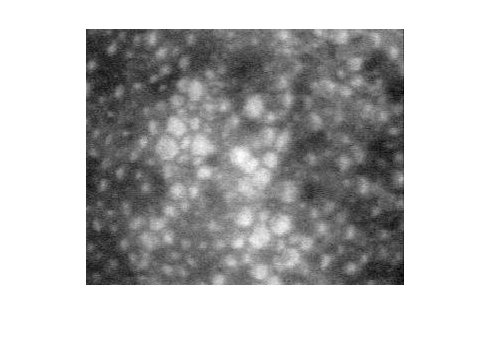

orig=imread('cornea.tif');
figure,imshow(orig)

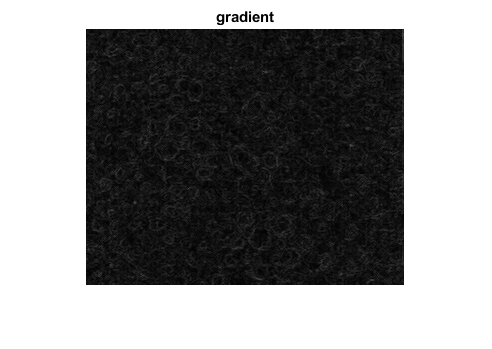


% calculem el gradient. Ho podem fer morfològic
ee=strel('disk',1);
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')

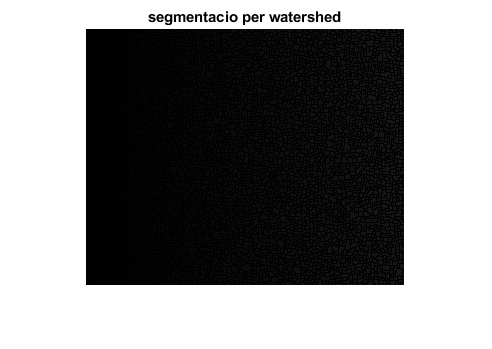


% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
figure,imshow(segm), title('segmentacio per watershed')

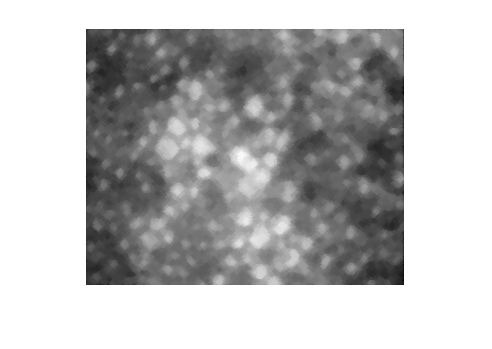

% resultat sobresegmentat. Cal treballar amb markers

%% marker-controlled watershed
% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)

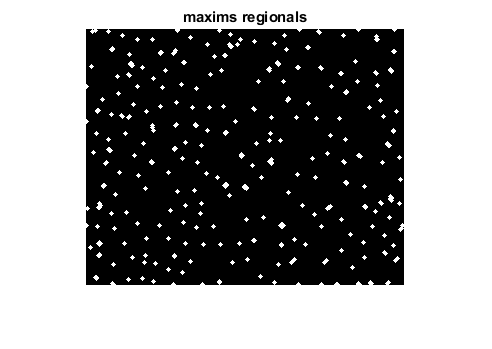

rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

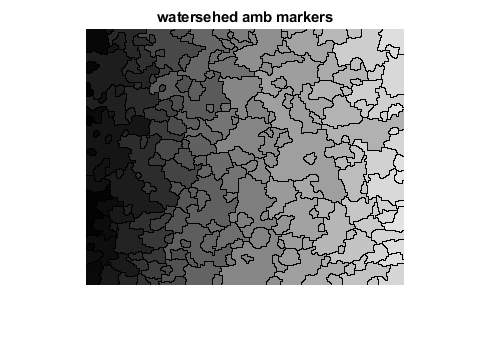


% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')

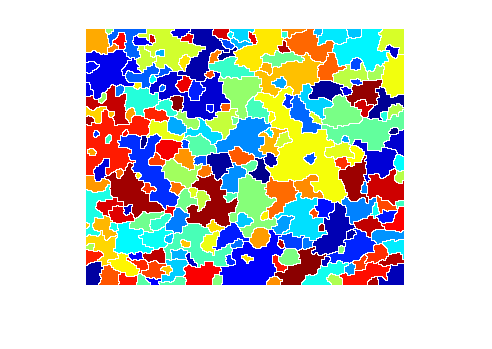


%Feu un overlay, en color, dels contorns obtinguts sobre la imatge original
%Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?

labelColors = label2rgb(segm,'jet','w','shuffle'); 
figure,imshow(labelColors)

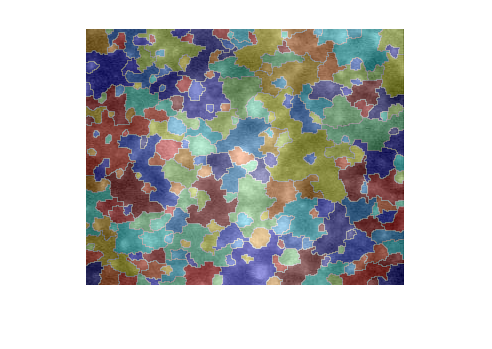

figure
imshow(orig)
hold on
himage = imshow(labelColors);
himage.AlphaData = 0.3;

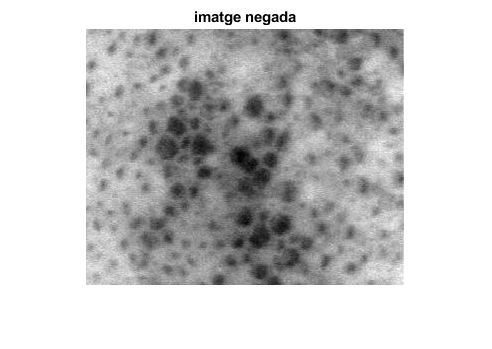


%%% Resposta: la segmentacio no es correcta, ens falta marcar el background
%%% per no falsejar el nombre de regions

%% Cal trobar un marker pel fons
% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

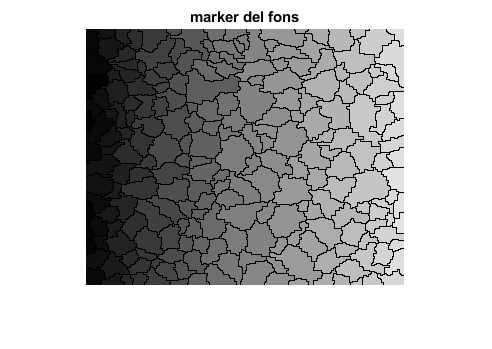

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

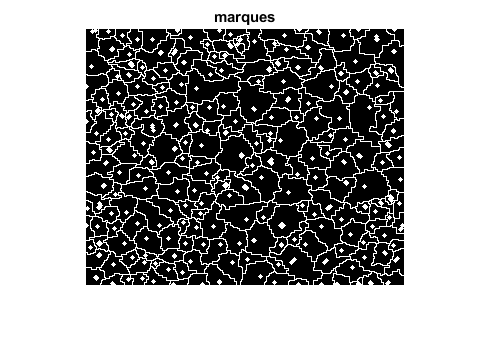


% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')

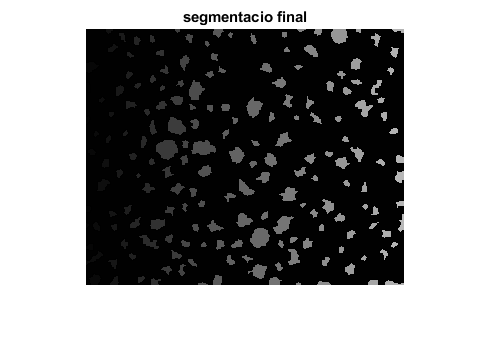


% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

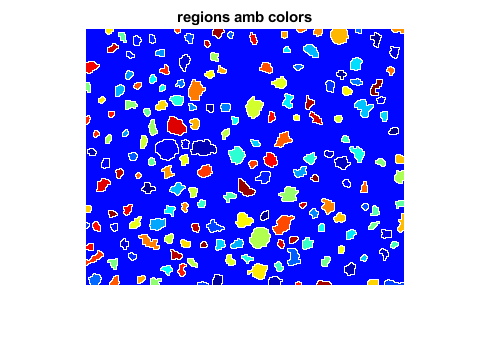

labelColors = label2rgb(segm,'jet','w','shuffle'); 
figure,imshow(labelColors), title("regions amb colors")

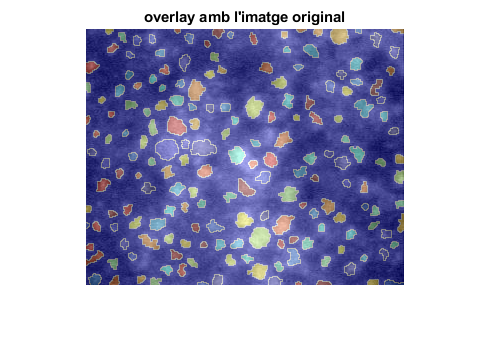

figure
imshow(orig), title ("overlay amb l'imatge original")
hold on
himage = imshow(labelColors);
himage.AlphaData = 0.3;

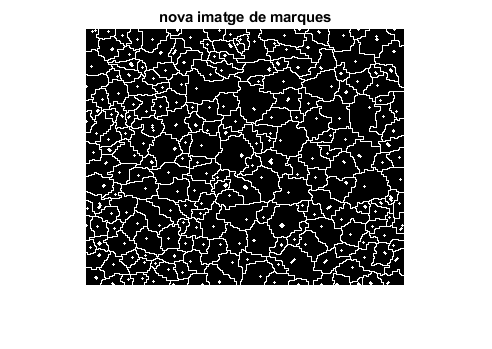


%% hem perdut alguna cèlula.
% Aixó és degut a que alguns markers de les celules es toquen amb el marker del fons (veure imatge  markers’)

% Utilitzeu operacions morfològiques sobre les imatges de marques per a evitar que els markers es
% toquin. Genereu una nova imatge de marques.
% Segmenteu la imatge amb watershed usant les noves marques i mostreu el resultat en overlay.

%%% RESPOSTA: Fem un nou element estrucutrant amb una forma semblant als
%%% markers i realitzem un imerode per reduir la mida dels markers i evitar
%%% que toquin el border
ee = strel('diamond',1);
rm = imerode(rm,ee);
markers=~fons|rm;
figure,imshow(markers),title('nova imatge de marques')

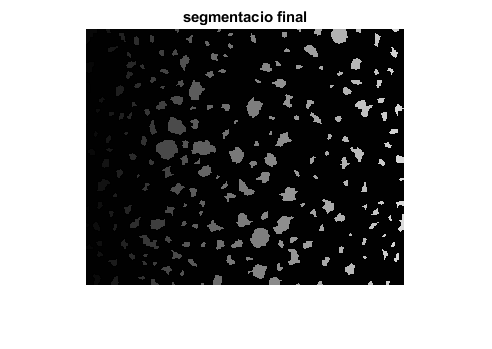

segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

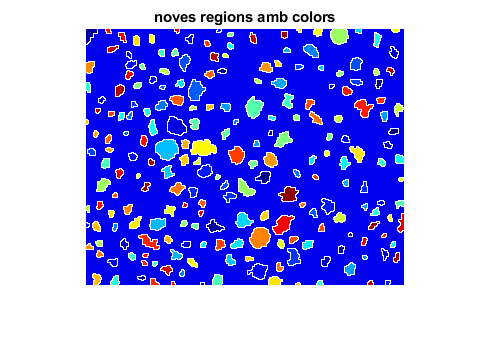

labelColors = label2rgb(segm,'jet','w','shuffle'); 
figure,imshow(labelColors), title("noves regions amb colors")

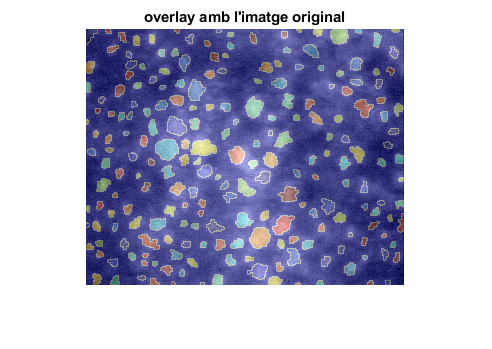

figure
imshow(orig), title ("overlay amb l'imatge original")
hold on
himage = imshow(labelColors);
himage.AlphaData = 0.3;

## Segmentació per clustering. K-Means

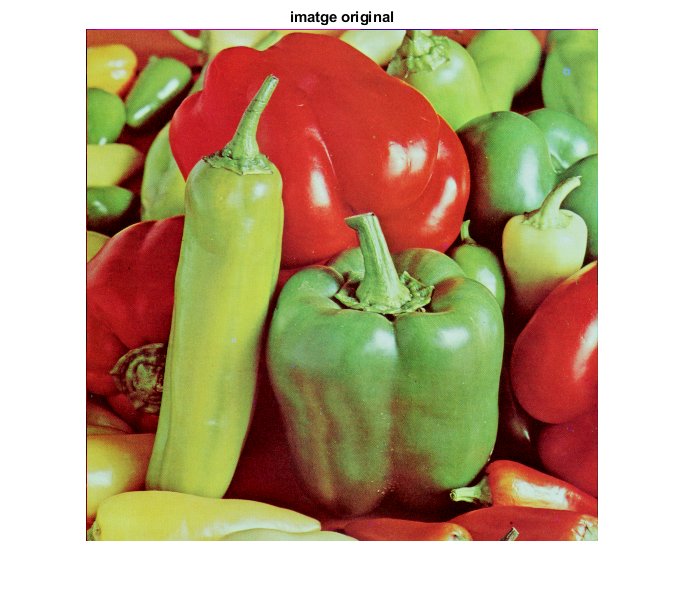

im=imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure,imshow(im),title('imatge original')

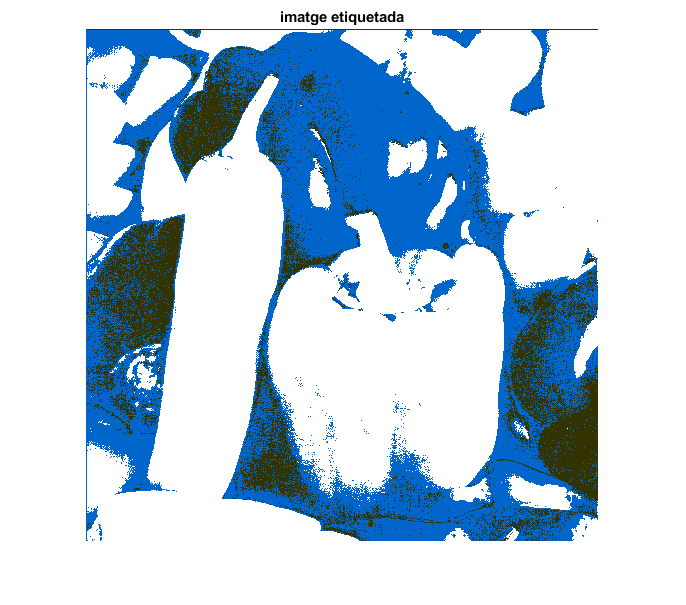


% la segmentarem per color. Treballarem en l'espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);

vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre

% Usarem la funció kmeans amb distancia citiblock 
[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

% Consulteu al help els paràmetres de la funció kmeans
%% 1r paràmetre: matriu a particionar, en aquest cas vector
%% 2n paràmetre: Nombre de clusters
%% La resta són paràmetres opcionals. En el nostre cas:
%% 'Distance' - Distance measure, in P-dimensional space, that KMEANS
%      should minimize with respect to.  Choices are:
%          'cityblock'    - Sum of absolute differences, a.k.a. L1 distance

% obtenim la imatge etiquetada pel número cluster
eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')


% Algo no va. 
% Els pebrots vermells queden mal segmentats. 
% (COMTE! EL RESULTAT DE KMEANS ÉS SEMPRE DIFERENT. 
% DEPÈN DE L'EXECUCIÓ, EL RESULTAT PODRIA SORTIT MILLOR O PITJOR)
% Què està passant ?